# `高温作业专用服装设计 `

## 背景

设计首要目标是避免高温环境下作业的人体皮肤灼伤，其次是降低研发成本，缩短研发周期。

实验场景：将体内温度控制在37ºC的假人放置在实验室的高温环境中，测量假人皮肤外侧的温度。

模型假设：

- 专用服装由三层织物材料构成，I、II、III层，其中I层与外界环境接触，III层与皮肤之间还存在空隙，将此空隙记为IV层。

- 假人体内恒温37℃。

## 求解问题

- 给定专用服装材料参数，对环境温度为75ºC、II层厚度为6 mm、IV层厚度为5 mm、工作时间为90分钟的情形开展实验，测量得到假人皮肤外侧的温度。建立数学模型，计算温度分布。

- 当环境温度为65ºC、IV层的厚度为5.5 mm时，确定II层的最优厚度，确保工作60分钟时，假人皮肤外侧温度不超过47ºC，且超过44ºC的时间不超过5分钟。

- 当环境温度为80时，确定II层和IV层的最优厚度，确保工作30分钟时，假人皮肤外侧温度不超过47ºC，且超过44ºC的时间不超过5分钟。

## 模型假设

- 不考虑作业服水汽、汗液蒸发等传热传质过程

- 以第IV层（空气层）底层温度表示人体皮肤外侧温度

- 不考虑接触面之间的接触热阻，认为接触界面连续

- 简化为一维传热问题，不考虑其他不均匀热源和传热过程

## `读取给定参数`

### 附件1. 专业服装材料参数

clear, close, clc
% 读入材料参数
file = 'CUMCM2018A_data.xlsx';
materials = readtable(file,'Sheet','Appendix 1',...
    'Range','A2:E6',...
    'ReadVariableNames',true);

% 修改变量名
materials.Properties.VariableNames = {'layer','density','specificHeat','thermalConductivity','thickness'};


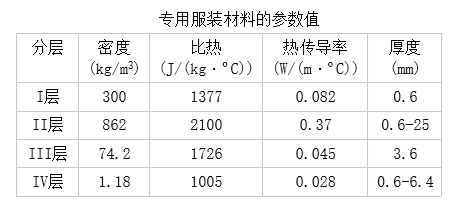

### 附件2. 问题1温度测试数据

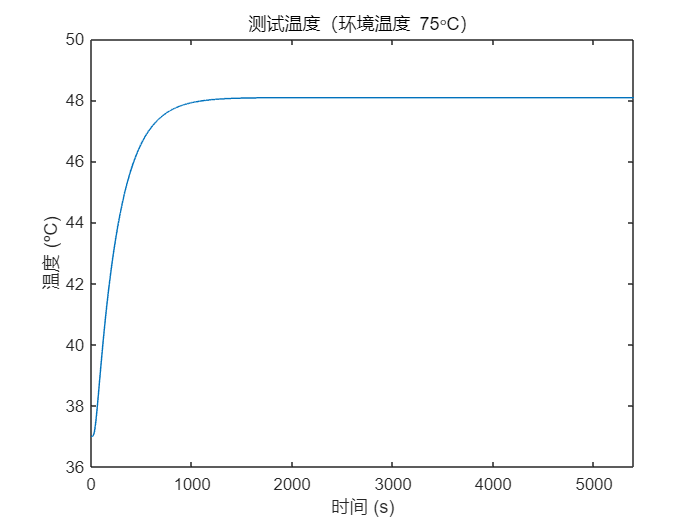

% 读入温度测试数据
sheet = 2;
[data,labels,~] = xlsread(file,sheet);
% 可视化测试数据
figure
plot(data(:,1),data(:,2))
xlim([0,2400])
xlabel(labels(2,1))
ylabel(labels(2,2))
xlim([0 5400])
ylim([36.0 50.0])
title('测试温度（环境温度 75\circC）')

## **问题一求解：传热模型参数的优化**

基本参数和模型的定义

tic % 记录问题一的求解时间
% 2D模型几何参数赋值,各层厚度单位为m
d1 = 0.6*1e-3;
d2 = 6*1e-3;
d3 = 3.6*1e-3;
d4 = 5*1e-3;
% 材料层边界x坐标
x1 = 0 + d1;
x2 = x1 + d2;
x3 = x2 + d3;
x4 = x3 + d4;
% 高度
l = 20*1e-2/4;
% 几何结构
Rect = [3,4,0,x4,x4,0,0,0,l,l];
g = decsg(Rect');
% 创建2D传热模型，用于求解瞬态过程
mdl = createpde('thermal','transient');
% 创建2D几何结构
geometryFromEdges(mdl,g);

可视化模型的局部结构

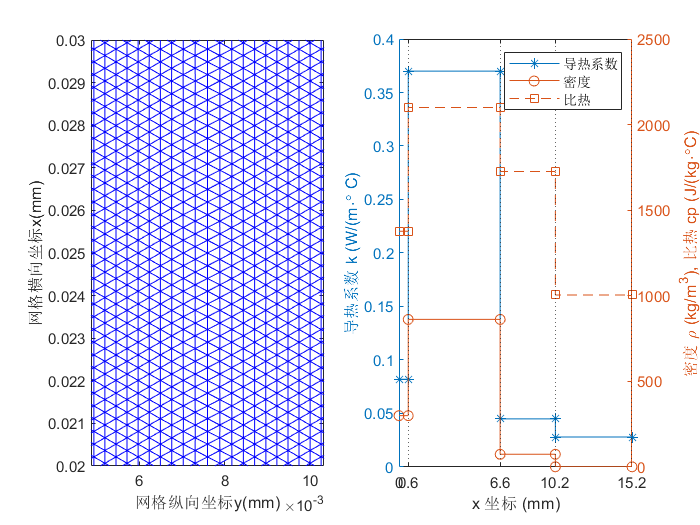

figure
% 生成网格并可视化
msh = generateMesh(mdl,'Hmax',d1/2);
subplot(1,2,1)
pdeplot(mdl)
xlabel('网格纵向坐标y(mm)');
ylabel('网格横向坐标x(mm)');

ylim([0.02,0.03])
% 定义材料属性
kfunc = @(location,state) interp1([0,x1,x2,x3,x4],[materials.thermalConductivity;materials.thermalConductivity(end)],location.x,'previous');
rho = @(location,state) interp1([0,x1,x2,x3,x4],[materials.density;materials.density(end)],location.x,'previous');
cp = @(location,state) interp1([0,x1,x2,x3,x4],[materials.specificHeat;materials.specificHeat(end)],location.x,'previous');
thermalProperties(mdl,'ThermalConductivity',kfunc,'MassDensity',rho,'SpecificHeat',cp);

% 可视化材料属性在x轴上的变化
subplot(1,2,2)
location.x = [0:0.00005:x4];
loc.x = [0,x1-eps,x1,x2-eps,x2,x3-eps,x3,x4-eps,x4];
% 热传导率
yyaxis left
plot(loc.x,kfunc(loc,[]),'*-')
ylabel('导热系数 k (W/(m\cdot\circ C)')
% 密度和比热
yyaxis right
hold on
plot(loc.x,rho(loc,[]),'o-')
hold on
plot(loc.x,cp(loc,[]),'s--')
ylabel('密度 \rho (kg/m^3), 比热 cp (J/(kg\cdot\circC)')
% 各层边界位置
xline(x1,':');
xline(x2,':');
xline(x3,':');
xline(x4,':');
hold off
legend({'导热系数','密度','比热'})
% 将x坐标单位修改为mm
xticks([0,x1,x2,x3,x4])
xticklabels({num2str(0),num2str(x1*1e3),num2str(x2*1e3),...
    num2str(x3*1e3),num2str(x4*1e3)})
xlabel('x 坐标 (mm)')

根据初值仿真模型求解结果

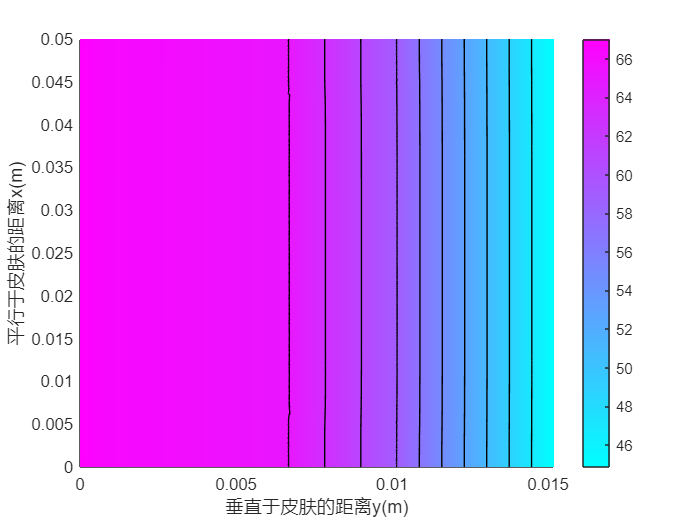

% 定义仿真参数
Tenv = 75; % 环境温度
Tbody = 37; % 体表温度
% 参数估计：第三类边界条件的对流换热系数
% 设置初始值
CCoef0 = [10,10]; 
h1 = CCoef0(1);
h2 = CCoef0(2);
% 设定仿真边界条件及待估计参数初始值
thermalBC(mdl,'Edge',4,'AmbientTemperature',Tenv,'ConvectionCoefficient',h1);
thermalBC(mdl,'Edge',2,'AmbientTemperature',Tbody,'ConvectionCoefficient',h2);
thermalIC(mdl,Tbody);
% 变步长求解温度瞬态变化
% 仿真时间点
tlist = [0:15:45,60:2*60:26*60,30*60:15*60:90*60];
R = solve(mdl,tlist);
T = R.Temperature;
% 后处理
% 生成温度场的仿真结果动画
figure
for i = 1:numel(tlist)
    pdeplot(mdl,'XYData',T(:,i),'Contour','on')
    xlim([0,x4])
    M(i) = getframe;
end
% 在命令行输入以下代码，查看仿真结果动画，n代表查看次数
n = 2;
movie(M,n)
xlabel('垂直于皮肤的距离y(m)');
ylabel('平行于皮肤的距离x(m)');


% 查找离目标观测点(x0,y0)最近的节点，对仿真结果进行插值
xx0 = x4;
yy0 = l/2;
getClosestNode = @(p,x,y,z) min((p(1,:)-x).^2 + (p(2,:)-y).^2);
[~,nid] = getClosestNode(mdl.Mesh.Nodes,xx0,yy0);
simData = interp1(tlist,T(nid,:),data(:,1),'linear');
% 评估仿真和测试数据间的差异
rsse = sqrt(sum((simData-data(:,2)).^2))

rsse = 315.6436

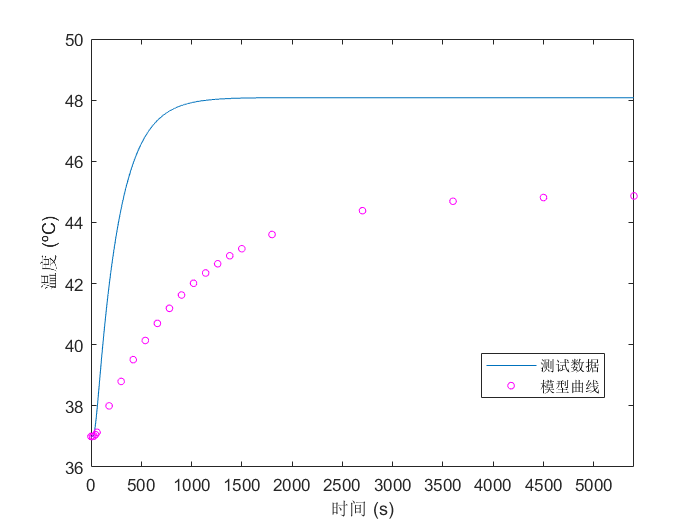

% 对该节点的数据进行可视化，并与测试数据进行对比
figure
hold on
plot(data(:,1),data(:,2))
plot(tlist,T(nid,:),'mo','MarkerSize',4)
hold off
legend({'测试数据','模型曲线'},'Location','best')
xlabel(labels(2,1))
ylabel(labels(2,2))
xlim([0,5400])
ax = gca;
ax.Box = 'on';

利用最小二乘法优化参数并仿真结果


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3         7537.95                      3.57e+04
     1          6         141.588       0.718809       2.87e+03      
     2          9         16.6607        5.77233       1.51e+03      
     3         12         1.52386       0.403005           41.8      
     4         15         1.46406      0.0702944          0.119      
     5         18         1.46406    0.000597006        0.00195      
     6         21         1.46406    1.04694e-05       0.000123      


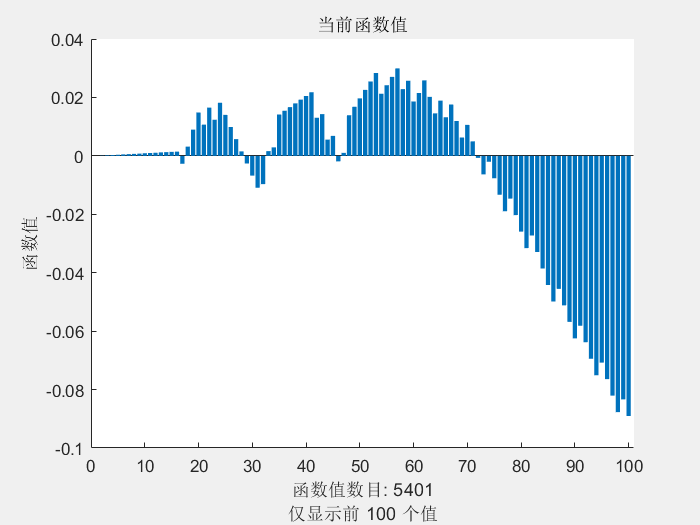


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


CCoef =   121.3165    8.3948


res =          0
    0.0001
    0.0002
    0.0003
    0.0004
    0.0005
    0.0006
    0.0007
    0.0008
    0.0009


% 利用优化算法估计边界条件中的热传导系数
options_op = optimoptions('lsqcurvefit','Display','iter','UseParallel',false,'PlotFcn','optimplotfval');
func = @(x,xdata)evaluationfun(x(1),x(2),xdata,mdl,Tenv,Tbody,x4,l/2,tlist);
% 参数估计初始值
h1 = 10; h2 = 10;
% 利用最小二乘法进行参数估计
% 通过最小化仿真结果和测试曲线对比的残差实现
[CCoef,~,res] = lsqcurvefit(func,[h1,h2],data(:,1),data(:,2),[50,2],[300,50],options_op)

h1 = CCoef(1); % 环境与第一层材料之间的对流系数
h2 = CCoef(2); % 假人与最后一层材料之间的对流系数
disp(['对流传热系数h1=' num2str(h1)]);

对流传热系数h1=121.3165


disp(['对流传热系数h2=' num2str(h2)]);

对流传热系数h2=8.3948



% 查看参数优化后的结果
% 更新仿真边界条件
thermalBC(mdl,'Edge',4,'AmbientTemperature',Tenv,'ConvectionCoefficient',CCoef(1));
thermalBC(mdl,'Edge',2,'AmbientTemperature',Tbody,'ConvectionCoefficient',CCoef(2));

% 重新求解并评估模型参数估计效果
R = solve(mdl,tlist);
T = R.Temperature;
simData = interp1(tlist,T(nid,:),data(:,1),'linear');
rsse = sqrt(sum((simData-data(:,2)).^2))

rsse = 1.2100

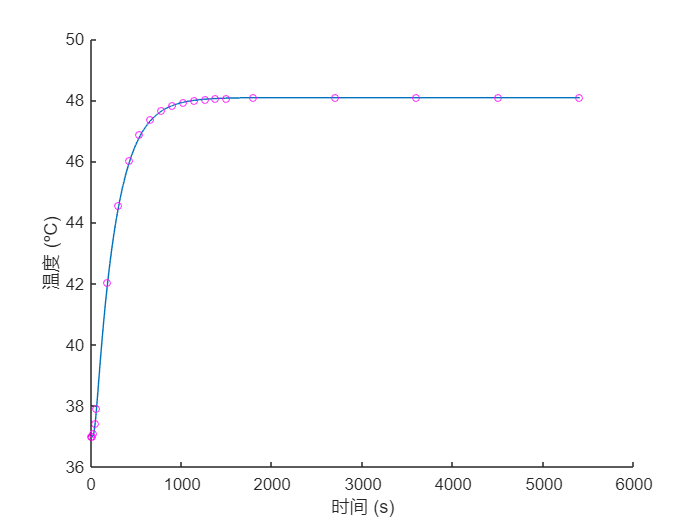

figure
hold on
plot(data(:,1),data(:,2))
plot(tlist,T(nid,:),'mo','MarkerSize',4)
xlabel(labels(2,1))
ylabel(labels(2,2))
hold off

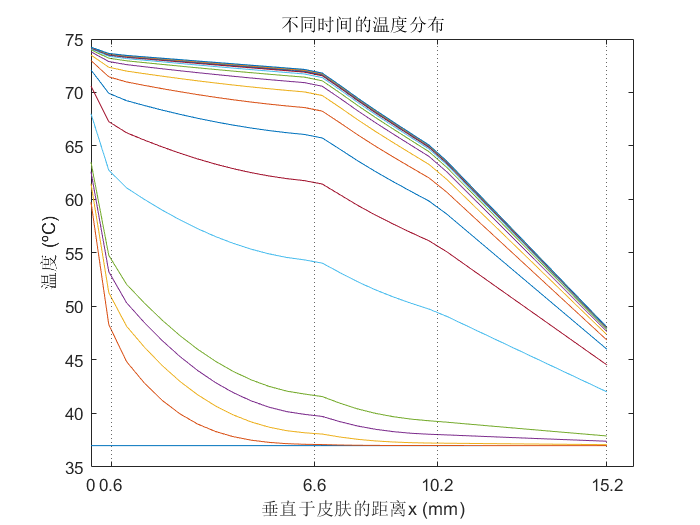


% 对模型中轴线上的多个观测点在每个仿真计算时间的温度进行可视化
XG = linspace(0,x4,30);
YG = l/2*ones(1,length(XG));
idx = zeros(1,length(XG));
for i = 1:numel(XG)
    [~,idx(i)] = getClosestNode(mdl.Mesh.Nodes,XG(i),YG(i));
end
plot(XG,T(idx,:))
hold on
xline(x1,':');
xline(x2,':');
xline(x3,':');
xline(x4,':');
hold off
xticks([0,x1,x2,x3,x4])
xticklabels({num2str(0),num2str(x1*1e3),num2str(x2*1e3),...
    num2str(x3*1e3),num2str(x4*1e3)})
xlabel('垂直于皮肤的距离x (mm)')
ylabel(labels(2,2))
title('不同时间的温度分布')


Pro1Time =toc % 显示问题一的求解时间

Pro1Time = 334.3041

## **问题二求解：第二层厚度的单变量优化模型**

给定条件：环境温度为65℃，工作60分钟，第四层厚度为5.5 mm。

约束条件：体表最大温度不能超过47℃，且超过44℃的时间低于5分钟。

优化目标：寻找第二层材料厚度的最小值。

**注意：**为方便理解，优化过程中厚度单位均采用mm。

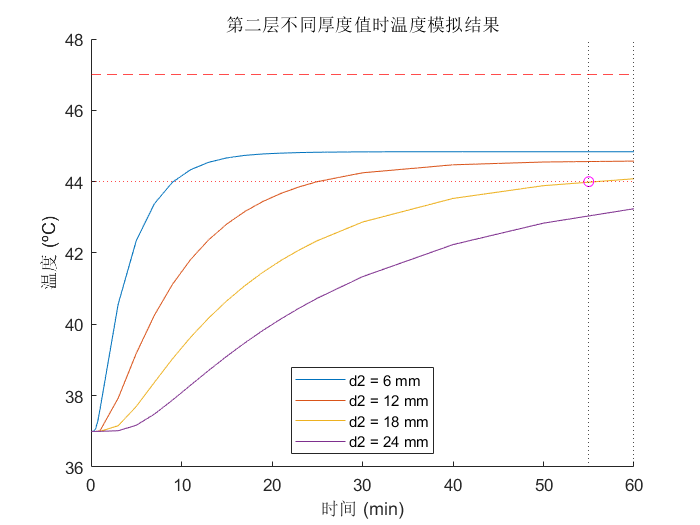

tic %  记录问题二的求解时间
% 仿真条件
Tenv = 65;
endTime = 60*60;
tlist = [0:15:45, 60:2*60:25*60, 30*60:10*60:endTime];
tRange = 0:endTime;

% 定步长给定第二层厚度值，估计目标最优值
dd4 = 5.5;
dd2 = [6 12 18 24];
mSize = 1e-3;
figure
hold on

for d2 = dd2
    [c,~] = constr(d2,dd4,mSize,materials,CCoef(1),CCoef(2),Tenv,Tbody,tlist,tRange);
end

plotAuxilliaryLines(endTime)
hold off
legend({'d2 = 6 mm','d2 = 12 mm','d2 = 18 mm','d2 = 24 mm'},'location','south')
xlim([0 60])
ylim([36,48])
xlabel('时间 (min)')
ylabel(labels(2,2))
title('第二层不同厚度值时温度模拟结果')

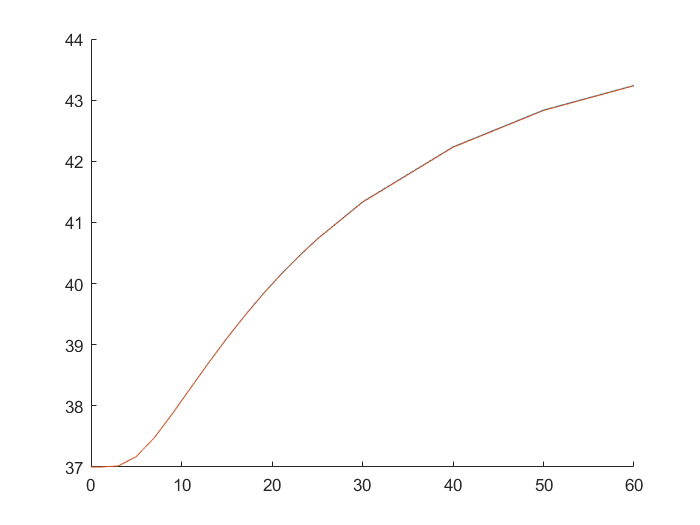

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           2    2.400000e+01     0.000e+00     1.000e+00     0.000e+00     1.000e+00  
    1           4    2.300000e+01     0.000e+00     1.000e+00     1.000e+00     1.000e+00  
    2           6    1.800000e+01     0.000e+00     1.000e+00     5.000e+00     1.000e+00  
    3           9    1.792600e+01     0.000e+00     1.000e+00     7.400e-02     1.000e+00  
    4          26    1.780829e+01     0.000e+00     6.782e-03     1.177e-01     3.327e-01  
    5          29    1.779078e+01     0.000e+00     1.000e+00     1.751e-02     1.113e+01  
    6          31    1.778933e+01     0.000e+00     1.000e+00     1.448e-03     1.000e+00  
    7          33    1.778847e+01     0.000e+00     1.000e+00     8.678e-04     2.200e-01  
    8          35    1.778536e+01     0.000e+00     1.000e+00     3.101e-03     7.

sol2 = 17.7655

fval2 = 17.7655

output2 = 包含以下字段的 struct :
         iterations: 18
          funcCount: 64
          algorithm: 'sqp'
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 1.682559e-16,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
    constrviolation: 0
           stepsize: 0
       lssteplength: 1
      firstorderopt: 1.6826e-16
       bestfeasible: [1×1 struct]



% 给定第四层厚度，及待优化参数第二层厚度的初始值
dd4 = 5.5; % 单位 mm
dd2 = 24;  % 单位 mm

% 基于求解器的优化过程 solver-based
fun = @(x) x;
gfun = @(x) constr(x,dd4,mSize,materials,CCoef(1),CCoef(2),Tenv,Tbody,tlist,tRange);
options = optimoptions('fmincon','Algorithm','sqp','MaxFunctionEvaluations',1000,...
    'FiniteDifferenceStepSize',0.001,'Display','iter','UseParallel',false, ...
    'PlotFcn',{'optimplotfval','optimplotconstrviolation','optimplotfirstorderopt'});

figure
hold on
[sol2,fval2,~,output2] = fmincon(fun,dd2,[],[],[],[],0.6,25,gfun,options)

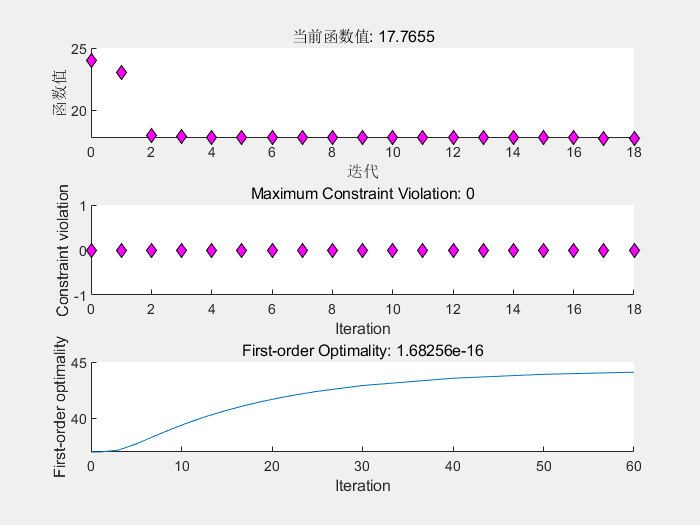

hold off

disp(['第二层材料厚度的最小值:' num2str(sol2)]);

第二层材料厚度的最小值:17.7655


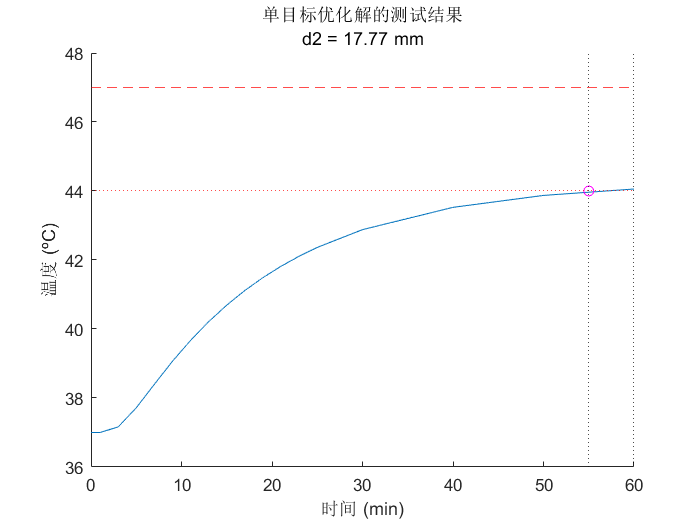


% 可视化第二层厚度的优化值及对应的仿真结果
figure
hold on
[test2,result2,x4] = Simulation(sol2,dd4,mSize,materials,CCoef(1),CCoef(2),Tenv,Tbody,tlist);
visualizePointTemp(test2,result2,tlist,tRange,x4,l/2);
plotAuxilliaryLines(endTime)

hold off
xlim([0 60])
ylim([36,48])
title({'单目标优化解的测试结果',['d2 = ',num2str(round(sol2,2)),' mm']})
xlabel('时间 (min)')
ylabel(labels(2,2))

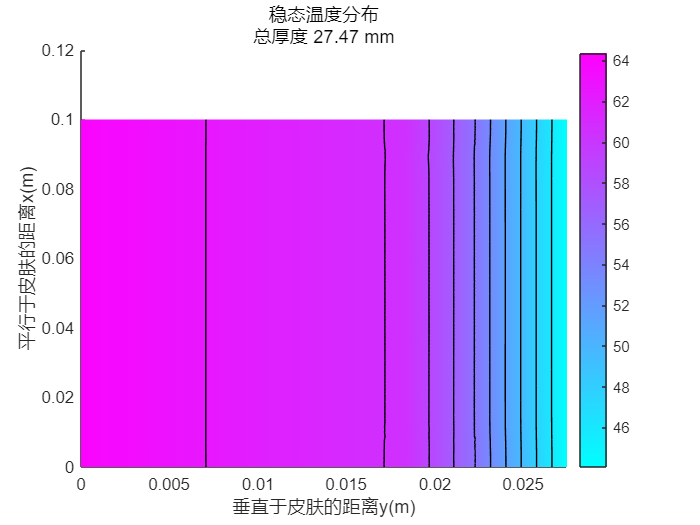

figure
pdeplot(test2,'XYData',result2.Temperature(:,end),'Contour','on')
xlim([0,x4])
title({'稳态温度分布';...
    ['总厚度 ',num2str(round(sol2+dd4+(d1+d3)*1e3,2)),' mm']})
xlabel('垂直于皮肤的距离y(m)');
ylabel('平行于皮肤的距离x(m)');


Pro2Time =toc % 显示问题二的求解时间

Pro2Time = 226.5365

## **问题三求解：第二层、第四层厚度的多目标优化模型**

给定条件：环境温度为80℃，工作30分钟。

约束条件：体表最大温度不能超过47℃，且超过44℃的时间低于5分钟。

优化目标：建立模型求解第二层和第四层厚度的最小值。

tic % 记录问题三的求解时间
% 仿真条件
Tenv = 80;
endTime = 30*60;
tlist = [0:15:45,60:2*60:endTime];
tRange = 0:endTime;
% 待优化参数初始值
dd4 = 5.5;
dd2 = 18;
% 待优化参数上下限
lb = [0.6 0.6];
ub = [25 6.4];

优化参数：$x(1)=d_2$, $x(2)=d_4$

目标函数：$f_1(x) = x(1)$, $f_2(x) =  x(2)$

% 目标优化函数
% 输入为待优化参数
objFunc = @(x)[x(1),x(2)];
% 约束函数
constrFunc = @(x) constr(x(1),x(2),mSize,materials,CCoef(1),CCoef(2),Tenv,Tbody,tlist,tRange);

% 算法1：gamultiobj
rng default
options = optimoptions('gamultiobj','UseParallel',false, 'MaxGenerations',500,'MaxTime',300,...
    'Display','iter','PlotFcn',{'gaplotpareto','gaplotscores'})

options =   gamultiobj 选项:

   设置属性:
                    Display: 'iter'
             MaxGenerations: 500
                    MaxTime: 300
                    PlotFcn: {'gaplotpareto'  'gaplotscores'}
                UseParallel: 0

   默认属性:
        ConstraintTolerance: 1.0000e-03
                CreationFcn: []
               CrossoverFcn: []
          CrossoverFraction: 0.8000
         DistanceMeasureFcn: {@distancecrowding  'phenotype'}
          FunctionTolerance: 1.0000e-04
                  HybridFcn: []
    InitialPopulationMatrix: []
     InitialPopulationRange: [2×1 double]
        InitialScoresMatrix: []
        MaxStallGenerations: 100
                MutationFcn: []
                  OutputFcn: []
             ParetoFraction: 0.3500
             PopulationSize: '50 when numberOfVariables <= 5, else 200'
             PopulationType: 'doubleVector'
               SelectionFcn


Multi-objective optimization:
2 Variable(s)
2 Nonlinear inequality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible


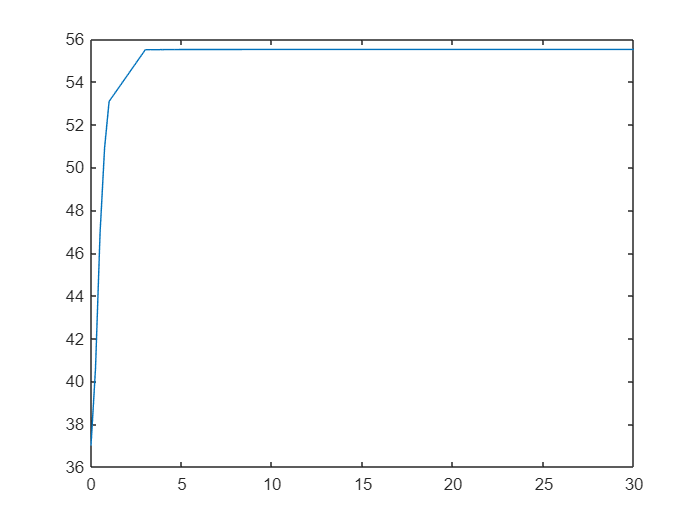


                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1            51                 1                 1
    2           101                 0                 0
    3           151          0.059642           0.85528
Optimization terminated: time limit exceeded.


sol3 =    20.8272    6.1381
   23.5183    3.9801
   21.3344    5.3547
   23.3533    4.0269
   24.4395    3.1483
   22.5525    5.0634
   22.1284    5.0749
   23.0025    4.0607


fval3 =    20.8272    6.1381
   23.5183    3.9801
   21.3344    5.3547
   23.3533    4.0269
   24.4395    3.1483
   22.5525    5.0634
   22.1284    5.0749
   23.0025    4.0607


flag3 = -5

output3 = 包含以下字段的 struct :
        problemtype: 'nonlinearconstr'
           rngstate: [1×1 struct]
        generations: 3
          funccount: 151
            message: 'Optimization terminated: time limit exceeded.'
      maxconstraint: 0
    averagedistance: 0.0596
             spread: 0.8553


population3 =    22.0927    4.4097
   24.0025    3.0607
   20.8838    4.7297
   23.9767    2.8077
   20.8272    6.1381
   23.4168    5.9337
   23.5183    3.9801
   20.5960    4.1311
   17.9174    5.3669
   20.6418    3.5694


scores3 =        Inf       Inf
       Inf       Inf
       Inf       Inf
       Inf       Inf
   20.8272    6.1381
   23.4168    5.9337
   23.5183    3.9801
       Inf       Inf
       Inf       Inf
       Inf       Inf



[sol3,fval3,flag3,output3,population3,scores3] = gamultiobj(objFunc,2,[],[],[],[],...
    lb,ub,constrFunc,options)

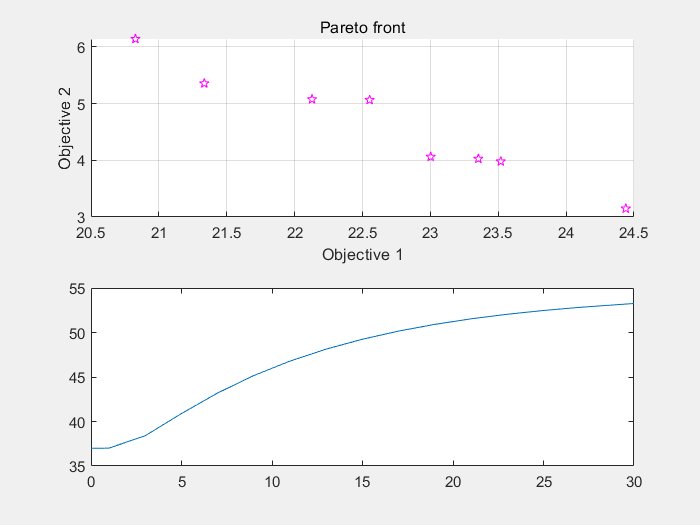


Iter   F-count   NumSolutions  Spread       Volume 
   0         5         4          -         5.8198e+00
   1        22         7          -         1.5680e+01

Time limit exceeded.



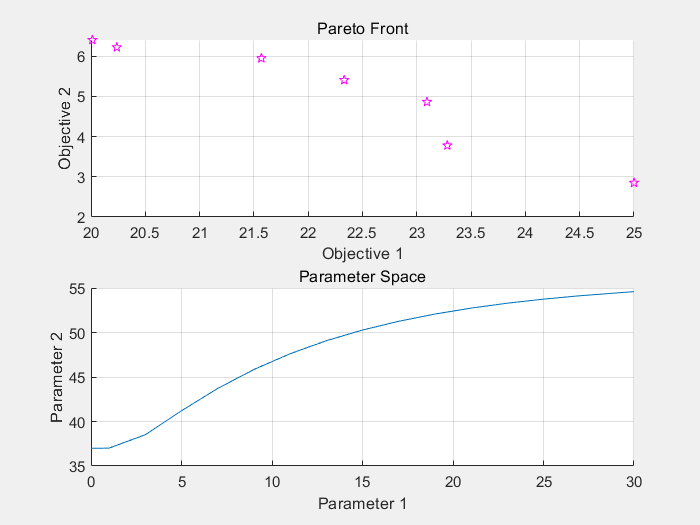


% 算法2：paretosearch
rng default
options = optimoptions('paretosearch','Display','iter','MaxFunctionEvaluations',1000,'MaxTime',300,...
    'PlotFcn',{'psplotparetof' 'psplotparetox'});
[sol4,fval4,flag4,output4,residuals4] = paretosearch(objFunc,2,[],[],[],[],...
    lb,ub,constrFunc,options);

可视化优化结果

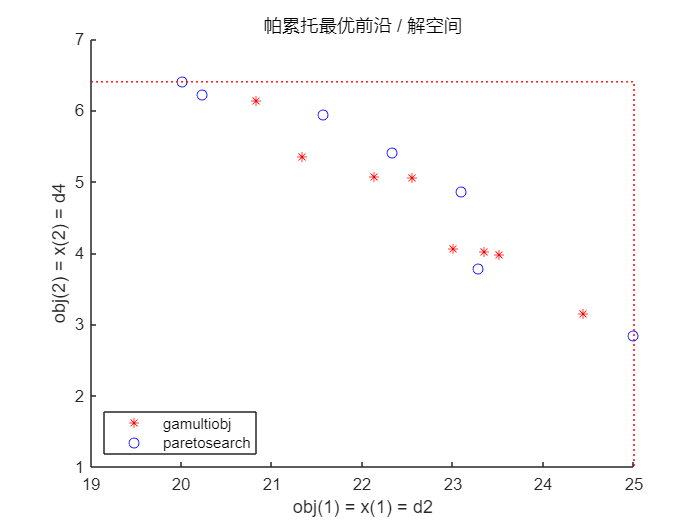

% 比较两种算法（gamultiobj和paretosearch）的优化结果
% 优化目标即是输入参数，因此帕累托最优前沿和参数空间一致
figure
hold on
plot(sol3(:,1),sol3(:,2),'r*')
plot(sol4(:,1),sol4(:,2),'bo')

plot([lb(1),ub(1)],[ub(2),ub(2)],'r:');
plot([ub(1),ub(1)],[lb(1),ub(2)],'r:');
xlim([19,25])
ylim([1,7])
hold off
xlabel('obj(1) = x(1) = d2')
ylabel('obj(2) = x(2) = d4')
title('帕累托最优前沿 / 解空间')
legend({'gamultiobj','paretosearch'},'location','southwest')


% 可视化采用gamultiobj算法对第一种优化目标设置的计算和热场分布仿真结果
[~,idxmax] = max(sol3(:,1));
[~,idxmin] = min(sol3(:,1));
[minM,bestId] = min(sum(sol3,2));
bestd2 = sol3(bestId,1);
bestd4 = sol3(bestId,2);
disp(['第二层材料最优厚度:' num2str(bestd2)]);

第二层材料最优厚度:21.3344


disp(['第四层材料最优厚度:' num2str(bestd4)]);

第四层材料最优厚度:5.3547


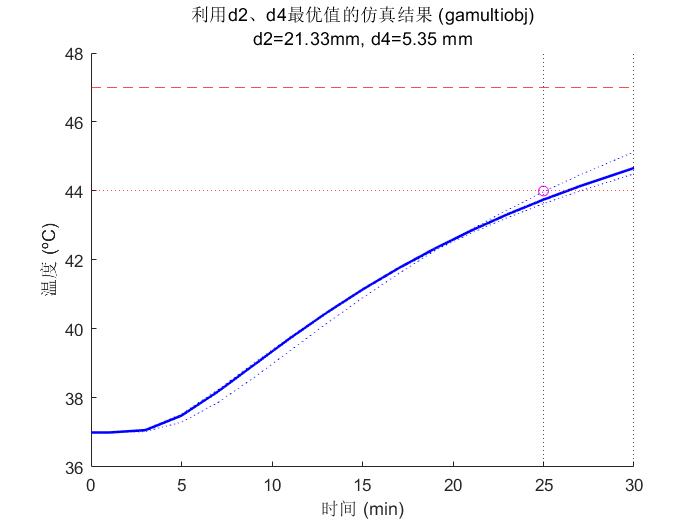


figure
hold on
[test,result,x4] = Simulation(sol3(idxmax,1),sol3(idxmax,2),mSize,materials,CCoef(1),CCoef(2),Tenv,Tbody,tlist);
ax1 = visualizePointTemp(test,result,tlist,tRange,x4,l/2);
ax1.LineStyle = ':';
ax1.Color = 'b';
[test,result,x4] = Simulation(sol3(idxmin,1),sol3(idxmin,2),mSize,materials,CCoef(1),CCoef(2),Tenv,Tbody,tlist);
ax2 = visualizePointTemp(test,result,tlist,tRange,x4,l/2);
ax2.LineStyle = ':';
ax2.Color = 'b';
[test,result,x4] = Simulation(bestd2,bestd4,mSize,materials,CCoef(1),CCoef(2),Tenv,Tbody,tlist);
ax3 = visualizePointTemp(test,result,tlist,tRange,x4,l/2);
ax3.LineWidth = 1.5;
ax3.Color = 'b';
plotAuxilliaryLines(endTime);
hold off
partOfTitle = ['d2=',num2str(round(bestd2,2)),'mm, d4=',num2str(round(bestd4,2)),' mm'];
xlabel('时间 (min)')
ylabel(labels(2,2))
title({'利用d2、d4最优值的仿真结果 (gamultiobj)';partOfTitle})

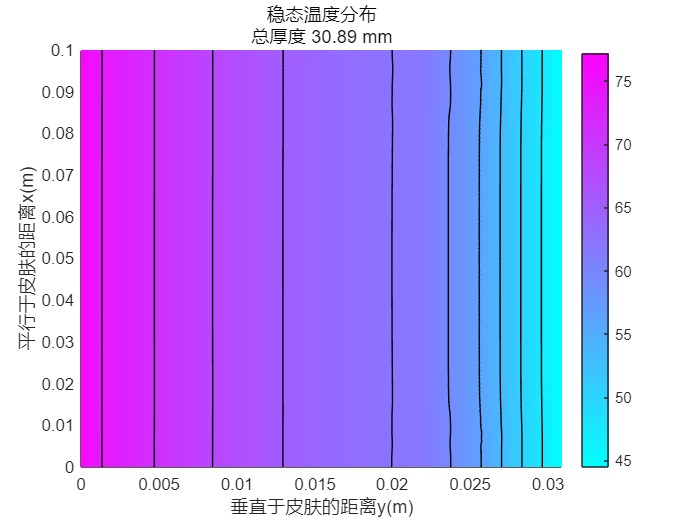

figure
pdeplot(test,'XYData',result.Temperature(:,end),'Contour','on')
xlim([0,x4])
title({'稳态温度分布';['总厚度 ',num2str(round(bestd2+bestd4+(d1+d3)*1e3,2)),' mm']})
xlabel('垂直于皮肤的距离y(m)');
ylabel('平行于皮肤的距离x(m)');


Pro3Time =toc % 显示问题三的求解时间

Pro3Time = 767.6073

## 辅助函数

可视化函数

1. 可视化离坐标点(x0,y0)最近的节点随时间的温度变化

function ax = visualizePointTemp(model,result,tlist,tRange,x0,y0)   
    getClosestNode = @(p,x,y,z) min((p(1,:)-x).^2 + (p(2,:)-y).^2);
    T = result.Temperature;
    [~,idx] = getClosestNode(model.Mesh.Nodes,x0,y0);
    interpTemp = interp1(tlist,T(idx,:),tRange,'linear','extrap');
    
    ax = plot(tRange/60,interpTemp);
    xlabel('时间 (min)')
    ylabel('温度 (\circC)')
end

2. 对沿(0,yy0)到(xx0,yy0)的直线上各点温度进行插值，并可视化其温度变化过程

function ax = visualizeTemperatureDistribution(result,tlist,xx0,yy0)
    XG = linspace(0,xx0,30);
    YG = yy0*ones(1,length(XG));
    querypoints = [XG(:),YG(:)]';
    Tinterp = interpolateTemperature(result,querypoints,1:length(tlist));
    ax = plot(XG,Tinterp(:,length(tlist)));
end

3. 在图中加入辅助线

function plotAuxilliaryLines(endTime)
    xline(endTime/60-5,'k:'); 
    xline(endTime/60,'k:'); 
    yline(44,'r:');
    yline(47,'r--');
    plot((endTime/60-5),(44),'mo')
end

计算函数

function simData = evaluationfun(h1,h2,xdata,model,Tenv,Tbody,x0,y0,tlist)
% 输入: 
% [h1,h2]: 对流系数
% xdata: 温度采样时间步长
% model: 待解模型
% Tenv, Tbody: 边界条件下的温度
% x0, y0: 测量温度点的坐标
% tlist: 瞬态仿真的时间步长
% 输出:
% simData: 模拟结果
    thermalBC(model,'Edge',4,'AmbientTemperature',Tenv,'ConvectionCoefficient',h1);
    thermalBC(model,'Edge',2,'AmbientTemperature',Tbody,'ConvectionCoefficient',h2);  
    thermalIC(model,Tbody);
    R = solve(model,tlist);
    getClosestNode = @(p,x,y,z) min((p(1,:)-x).^2 + (p(2,:)-y).^2);
    [~,idx] = getClosestNode(model.Mesh.Nodes,x0,y0);
    simData = interp1(tlist,R.Temperature(idx,:),xdata,'linear','extrap');
end

function [model,result,x4] = Simulation(dd2,dd4,mSize,materials,h1,h2,Tenv,Tbody,tlist)
% 输入:
% dd2,dd4: 第二层、第四层材料厚度
% materials: 材料属性
% h1,h2: 对流系数
% Tenv,Tbody: 边界条件下的温度
% tlist: 瞬态仿真的时间步长
% 输出:
% model: 基于给定输入的模型设置
% result: 瞬态仿真结果
% x4: 总厚度(包括间隙)
    model = createpde('thermal','transient');
    x1 = 0.6*1e-3;
    x2 = x1 + dd2*1e-3;
    x3 = x2 + 3.6*1e-3;
    x4 = x3 + dd4*1e-3;
    l = 10*1e-2;
    R = [3,4,0,x4,x4,0,0,0,l,l];
    g = decsg(R');
    geometryFromEdges(model,g);
    msh = generateMesh(model,'Hmax',mSize);

    k = @(location,state) interp1([0,x1,x2,x3,x4],[materials.thermalConductivity;materials.thermalConductivity(end)],location.x,'previous');
    rho = @(location,state) interp1([0,x1,x2,x3,x4],[materials.density;materials.density(end)],location.x,'previous');
    cp = @(location,state) interp1([0,x1,x2,x3,x4],[materials.specificHeat;materials.specificHeat(end)],location.x,'previous');
    thermalProperties(model,'ThermalConductivity',k,'MassDensity',rho,'SpecificHeat',cp);
    thermalBC(model,'Edge',4,'AmbientTemperature',Tenv,'ConvectionCoefficient',h1);
    thermalBC(model,'Edge',2,'AmbientTemperature',Tbody,'ConvectionCoefficient',h2);  
    thermalIC(model,Tbody);
    result = solve(model,tlist);
end

function [obj,skinTmax,overheatDuration] = computeall(dd2,dd4,mSize,materials,h1,h2,Tenv,Tbody,tlist,tRange)
% 输入:
% dd2,dd4: 第二层、第四层材料厚度
% materials: 材料属性
% h1,h2: 对流系数
% Tenv,Tbody: 边界条件下的温度
% tlist: 瞬态仿真的时间步长
% tRange: 模拟结果的时间范围
% 输出:
% obj: 需要优化的参数
% skinTmax: 最大皮肤温度(应低于47摄氏度)
% overheatDuration: 皮肤过热持续时间(低于44度，少于5分钟)

    obj = dd2;
    [model,output,x4] = Simulation(dd2,dd4,mSize,materials,h1,h2,Tenv,Tbody,tlist);
    p = model.Mesh.Nodes;
    idx = p(1,:)>x4-eps;
    T = output.Temperature;
    skinTemp = max(T(idx,:),[],1);
    interpTemp = interp1(tlist,skinTemp,tRange,'linear','extrap');
    
    hold on
    plot(tRange,interpTemp)
    xline(tlist(end)-5*60,'k:');
    skinTmax = max(skinTemp);
    thresholdT = 44;
    yline(thresholdT,'k:');
    overheatDuration = nnz(interpTemp>thresholdT)/60;
    hold off
end

function [c,ceq] = constr(dd2,dd4,mSize,materials,h1,h2,Tenv,Tbody,tlist,tRange)
% 输入:
% dd2,dd4: 第二层、第四层材料厚度
% materials: 材料属性
% h1,h2: 对流系数
% Tenv,Tbody: 边界条件下的温度
% tlist: 瞬态仿真的时间步长
% tRange: 模拟结果的时间范围
% 输出:
% c: 约束向量
% max(skinT) - 47 <= 0
% overheatDuration - 5 <= 0

    [model,output,x4] = Simulation(dd2,dd4,mSize,materials,h1,h2,Tenv,Tbody,tlist);
    p = model.Mesh.Nodes;
    idx = p(1,:)>x4-eps;
    T = output.Temperature;
    skinTemp = max(T(idx,:),[],1);
    interpTemp = interp1(tlist,skinTemp,tRange,'linear','extrap');
    plot(tRange/60,interpTemp)
    thresholdT = 44;
    overheatDuration = nnz(interpTemp>thresholdT)/60;
    c = [max(skinTemp)-47 overheatDuration-5];
    ceq = [];
end

